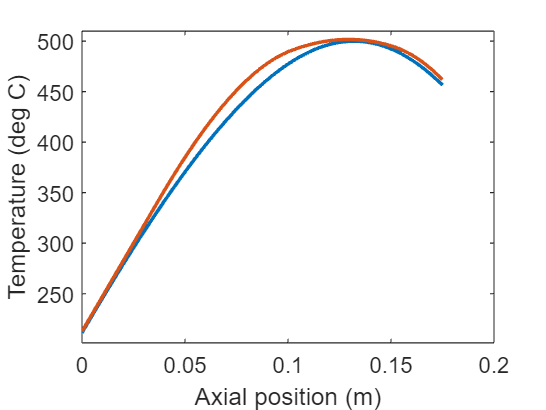

clear all 

%{
This program is used to check that the optimal of the 2^14 structures
achieved a maximum temperature within 0.5 deg. C of the set maximum
temperature to ensure a fair comparison. It was implemented on the data
generated with sweep1() for a set temeprture and flow rate. 
%}

load("f3_500_w2deg_buildcurve2.mat") %loading data generated from sweep1()

%calculating the isothermal metric 
del_c=convo-convo(1);
del_T=max(Temp')-Temp(:,end)'; 
met_iso=del_c./del_T; 

%index of structures 
structs=1:16384; 

%ranking 2^14 structures 
M=[met_iso',convo',structs',minmet',max(Temp')',struct]; 
M=sortrows(M,1);
M=flipud(M); 



%rerunning the top 30 structures
nredo=M(1:30,3); 
nredo=[0;nredo-1]; 


m=1; 
for n=nredo'
    if max(Temp(n+1,:))<499.5 || max(Temp(n+1,:))>500.5
        disp(m)
        Tinmin=bestT(n+1)-10;
        Tinmax=bestT(n+1)+10;
        Pinmin=bestP(n+1)-10;
        Pinmax=bestP(n+1)+10; 
        [Tredo(m,:),xval,Predo(m),Tagain(m),convo_redo(m),minmetredo(m),struct_redo(m,:)]=...
            Predict_Temp(n,Tinmin,Tinmax,Pinmin,Pinmax,3,500,0.5,2.34); %the last few entries will change with the data
        m=m+1; 
    else 
        Tredo(m,:)=Temp(n+1,:); 
        Predo(m)=bestP(n+1);
        Tagain(m)=bestT(n+1);
        convo_redo(m)=convo(n+1);
        minmetredo(m)=minmet(n+1);
        struct_redo(m,:)=struct(n+1,:); 
        m=m+1; 
    end
end

     2

     5

     6

     7

    11

    14

    16

    17

    18

    19

    20

    21

    27

    31



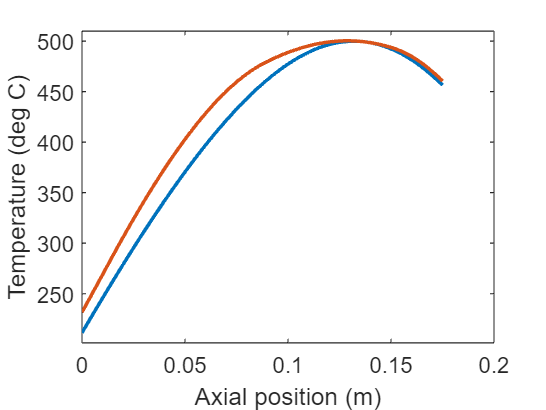

%resort the top 30 

delc2=convo_redo-convo_redo(1);
delT2=max(Tredo')-Tredo(:,end)';
metally=delc2./delT2;

M2=[metally',convo_redo',[1:31]',nredo,minmetredo',max(Tredo')',struct_redo];
M2=sortrows(M2);
M2=flipud(M2); 

%plotting the optimal structures 
plot(xval,Tredo(1,:),xval,Tredo(M2(1,3),:),"LineWidth",1.5)
xlabel("Axial position (m)")
ylabel("Temperature (deg C)")
ylim([min(Temp(1,:))-10 max(Temp(1,:))+10])


%save("f5_525_top30_buildcurve2.mat","metally","convo_redo","nredo","minmetredo","Tredo","xval","struct_redo")

